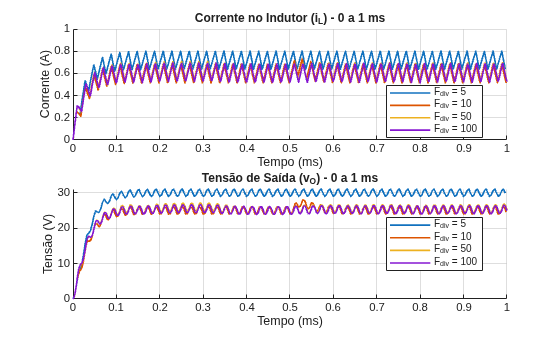

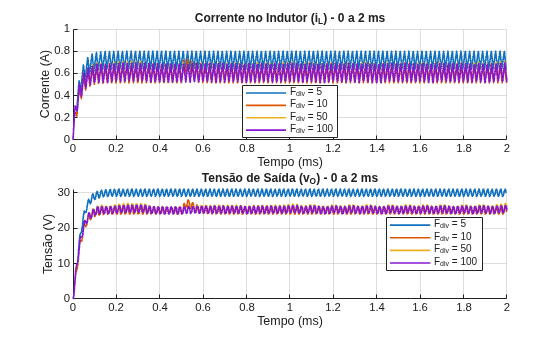

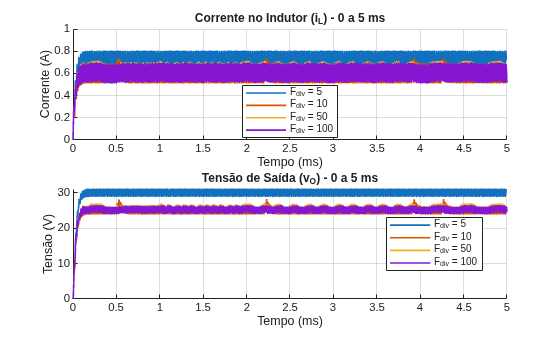

% =========================================================================
% Simulação Discreta de Conversor Buck (Método de Tustin)
% =========================================================================
clear; clc; close all;

t_total = double(5e-3);     % Tempo total de simulação (s) 10ms

% Vetor com os diferentes valores de F_div que você quer testar
F_div_testes = double([5, 10, 50, 100]); 

% Estruturas do tipo cell para armazenar vetores de tamanhos diferentes
resultados_t = cell(1, length(F_div_testes));
resultados_iL = cell(1, length(F_div_testes));
resultados_vO = cell(1, length(F_div_testes));

% Loop externo para testar cada valor de F_div
for idx_fdiv = 1:length(F_div_testes)
    F_div = double(F_div_testes(idx_fdiv));

    %% 1. Parâmetros de Simulação e do Conversor
    VS = double(50.0);             % Tensão de entrada (V)
    fs = double(50e3);             % Frequência de chaveamento (Hz)
    D  = double(0.5);              % Razão cíclica nominal
    L  = double(1.5e-3);           % Indutância (H)
    C  = double(0.18e-6);          % Capacitância (F)
    R  = double(41.7);             % Resistência de carga (Ohms)

    % Configuração de tempo e discretização
    Ts = double(1.0) / fs;         % Período de chaveamento (s)
    Tsim = double(Ts / F_div);     % Passo de simulação (s) 
    N_steps = double(floor(t_total / Tsim)); % Número total de passos

    %% 2. Constantes de Discretização (Tustin)
    K1 = double(Tsim / (double(2.0) * L));
    K2 = double((double(2.0) * R * C - Tsim) / (double(2.0) * R * C + Tsim));
    K3 = double((R * Tsim) / (double(2.0) * R * C + Tsim));

    % Constantes auxiliares para resolução do laço algébrico
    Den_alg = double(double(1.0) + double(K1 * K3));
    K_iL1   = double(double(1.0) - double(K1 * K3));
    K_iL2   = double(K1 * double(double(1.0) + K2));

    %% 3. Inicialização das Variáveis de Estado
    vs_old = double(VS);
    vs_new = double(VS);
    iL_old = double(0.0); 
    vO_old = double(0.0);

    % Vetores (pré-alocação explícita em double)
    t_array = double(double(0:N_steps-1) * Tsim);
    iL_array = zeros(1, N_steps, 'double');
    vO_array = zeros(1, N_steps, 'double');

    % Armazena as condições iniciais
    iL_array(1) = iL_old;
    vO_array(1) = vO_old;

    %% 4. Loop Principal de Simulação
    for k = 2:N_steps
        t_atual = double(t_array(k));
        
        vs_new = double(VS); 
        
        % Mapeia o tempo contínuo para a posição dentro do período
        t_no_periodo = double(mod(t_atual, Ts)); 
        
        if t_no_periodo < double(D * Ts)
            chave_fechada = true;
        else
            chave_fechada = false;
        end
        
        % --- Atualização das Variáveis de Estado ---
        if chave_fechada
            iL_new = double((double(iL_old * K_iL1) + double(K1 * (vs_new + vs_old)) - double(K_iL2 * vO_old)) / Den_alg);
        else
            iL_new = double((double(iL_old * K_iL1) - double(K_iL2 * vO_old)) / Den_alg);
        end
        
        vO_new = double(double(K2 * vO_old) + double(K3 * (iL_new + iL_old)));
        
        % --- Armazenamento para os Gráficos ---
        iL_array(k) = iL_new;
        vO_array(k) = vO_new;
        
        % --- Preparação para o Próximo Passo ---
        vs_old = vs_new;
        iL_old = iL_new;
        vO_old = vO_new;
    end
    
    resultados_t{idx_fdiv} = t_array;
    resultados_iL{idx_fdiv} = iL_array;
    resultados_vO{idx_fdiv} = vO_array;
end

%% 5. Geração dos Gráficos

periodos = double([1e-3, 2e-3, 5e-3]);
titulos = {'0 a 1 ms' , '0 a 2 ms', '0 a 5 ms'};

legendas = cell(1, length(F_div_testes));
for i = 1:length(F_div_testes)
    legendas{i} = ['F_{div} = ' num2str(double(F_div_testes(i)))];
end

for n = 1:length(periodos)

    figure('Name',['Resposta - ' titulos{n}], ...
           'NumberTitle','off');

    % Corrente do indutor
    subplot(2,1,1);
    hold on;
    for i = 1:length(F_div_testes)
        t_aux = double(resultados_t{i});
        iL_aux = double(resultados_iL{i});
        
        idx = (t_aux <= periodos(n));
        plot(t_aux(idx)*double(1e3), iL_aux(idx), 'LineWidth', 1.2);
    end
    hold off;
    grid on;
    xlabel('Tempo (ms)');
    ylabel('Corrente (A)');
    title(['Corrente no Indutor (i_L) - ' titulos{n}]);
    legend(legendas, 'Location', 'best');

    % Tensão de saída
    subplot(2,1,2);
    hold on;
    for i = 1:length(F_div_testes)
        t_aux = double(resultados_t{i});
        vO_aux = double(resultados_vO{i});
        
        idx = (t_aux <= periodos(n));
        plot(t_aux(idx)*double(1e3), vO_aux(idx), 'LineWidth', 1.2);
    end
    hold off;
    grid on;
    xlabel('Tempo (ms)');
    ylabel('Tensão (V)');
    title(['Tensão de Saída (v_O) - ' titulos{n}]);
    legend(legendas, 'Location', 'best');

end


%% 6. Verificação de Regime Permanente (Apenas 1 Período)
% ===============================================================
%  VERIFICAÇÃO DOS REQUISITOS DE PROJETO EM REGIME PERMANENTE
% ===============================================================

% Especificações de projeto
V_O_esp = double(25.0);           % Tensão de saída esperada (V)
I_L_esp = double(0.5995);         % Corrente no indutor esperada (A)
P_esp = double(15.0);             % Potência nominal (W)
delta_vO_max_perc = double(10.0); % Máxima ondulação de tensão permitida (%)
delta_iL_max_perc = double(30.0); % Máxima ondulação de corrente permitida (%)

% Tempo exato de 2 períodos de chaveamento
T_periodo = 2 * (double(1.0) / fs); 

for i = 1:length(F_div_testes)
    F_div_atual = F_div_testes(i);
    
    % Extrai os dados salvos da iteração atual
    t_aux = double(resultados_t{i});
    iL_aux = double(resultados_iL{i});
    vO_aux = double(resultados_vO{i});
    
    % Filtra apenas os índices correspondentes ao último período de chaveamento
    idx_ss = (t_aux >= (t_total - T_periodo));
    
    iL_ss = iL_aux(idx_ss);
    vO_ss = vO_aux(idx_ss);
    
    % 1. Cálculos de Valores Médios
    % Usamos (1:end-1) para não somar o limite do período duas vezes na média discreta
    V_O_med = mean(vO_ss(1:end-1));
    I_L_med = mean(iL_ss(1:end-1));
    P_med = (V_O_med^2) / R;
    
    % 2. Cálculos das Ondulações (Ripple) em Porcentagem
    % Para máximo e mínimo, podemos analisar o vetor inteiro
    delta_vO_perc = ((max(vO_ss) - min(vO_ss)) / V_O_med) * double(100.0);
    delta_iL_perc = ((max(iL_ss) - min(iL_ss)) / I_L_med) * double(100.0);
    
    % --- Exibição no Console ---
    fprintf('\n---> Teste para F_div = %d <---\n', F_div_atual);
    
    % Tensão de Saída
    fprintf('V_O médio : %.4f V \t(Projeto: ~%.2f V)\n', V_O_med, V_O_esp);
    
    % Corrente no Indutor
    fprintf('I_L médio : %.4f A \t(Projeto: ~%.4f A)\n', I_L_med, I_L_esp);
    
    % Potência
    fprintf('Potência  : %.4f W \t(Projeto: ~%.2f W)\n', P_med, P_esp);
    
    % Verificação de Ondulação da Tensão
    if delta_vO_perc <= delta_vO_max_perc
        fprintf('Delta V_O : %.2f %% \t\t[OK] (Projeto: %.1f %%)\n', delta_vO_perc, delta_vO_max_perc);
    else
        fprintf('Delta V_O : %.2f %% \t\t[FALHA] (Projeto: %.1f %%)\n', delta_vO_perc, delta_vO_max_perc);
    end
    
    % Verificação de Ondulação da Corrente
    if delta_iL_perc <= delta_iL_max_perc
        fprintf('Delta I_L : %.2f %% \t\t[OK] (Projeto: %.1f %%)\n', delta_iL_perc, delta_iL_max_perc);
    else
        fprintf('Delta I_L : %.2f %% \t\t[FALHA] (Projeto: %.1f %%)\n', delta_iL_perc, delta_iL_max_perc);
    end
end


---> Teste para F_div = 5 <---


V_O médio : 29.8788 V 	(Projeto: ~25.00 V)


I_L médio : 0.7298 A 	(Projeto: ~0.5995 A)


Potência  : 21.4087 W 	(Projeto: ~15.00 W)


Delta V_O : 7.00 % 		[OK] (Projeto: 10.0 %)


Delta I_L : 22.41 % 		[OK] (Projeto: 30.0 %)



---> Teste para F_div = 10 <---


V_O médio : 25.0085 V 	(Projeto: ~25.00 V)


I_L médio : 0.6072 A 	(Projeto: ~0.5995 A)


Potência  : 14.9982 W 	(Projeto: ~15.00 W)


Delta V_O : 8.85 % 		[OK] (Projeto: 10.0 %)


Delta I_L : 28.16 % 		[OK] (Projeto: 30.0 %)



---> Teste para F_div = 50 <---


V_O médio : 25.3648 V 	(Projeto: ~25.00 V)


I_L médio : 0.6067 A 	(Projeto: ~0.5995 A)


Potência  : 15.4286 W 	(Projeto: ~15.00 W)


Delta V_O : 9.34 % 		[OK] (Projeto: 10.0 %)


Delta I_L : 29.17 % 		[OK] (Projeto: 30.0 %)



---> Teste para F_div = 100 <---


V_O médio : 25.1819 V 	(Projeto: ~25.00 V)


I_L médio : 0.6031 A 	(Projeto: ~0.5995 A)


Potência  : 15.2069 W 	(Projeto: ~15.00 W)


Delta V_O : 9.14 % 		[OK] (Projeto: 10.0 %)


Delta I_L : 28.86 % 		[OK] (Projeto: 30.0 %)


disp('===============================================================');